flowerds = imageDatastore("Flowers","IncludeSubfolders",true,"LabelSource","foldernames");

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);

Determining the number of flower species

numClasses = numel(categories(flowerds.Labels));

Creating a network by modifying GoogLeNet

net = googlenet;
lgraph = layerGraph(net)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


Modifying the classification and output layers

newFc = fullyConnectedLayer(12,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 12

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


Setting training algorithm options

options = trainingOptions("sgdm","InitialLearnRate", 0.001);

Performing training

[flowernet,info] = trainNetwork(trainImgs, lgraph, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:24 |        7.81% |       4.5336 |          0.0010 |
|      13 |          50 |       00:13:48 |       98.44% |       0.1173 |          0.0010 |
|      25 |         100 |       00:27:13 |      100.00% |       0.0080 |          0.0010 |
|      30 |         120 |       00:32:45 |      100.00% |       0.0152 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


Using the trained network to classify test images

testpreds = classify(flowernet,testImgs);

Evaluating the results, calculating the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.8880

Visualizing the confusion matrix

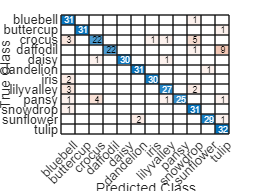

confusionchart(testImgs.Labels,testpreds);